clear;
clc;
close all;
rng(0);
load('left_arm_datawithrms.mat');
% load('left_arm_datanorms.mat');
% FeatureDataTable("max min mean std jerk",table_of_recordings,250);
[y1, targets, datar] = RegressionNeuralNetwork(left_arm_data,10,40,20,70,30,true);

RMSE on the test set is 0.165898



% [classes, targetvals, datac] = ClassificationNeuralNetwork(left_arm_data,84,75,15,10,true);


t = tiledlayout('flow');
t.Title.String = 'Error Histogram';
t.Padding = 'compact';
t.TileSpacing ='compact';
 
nexttile
ErrorInfo(y1,targets)

ans =   Figure (PLOTERRHIST1) with properties:

      Number: 1
        Name: 'Error Histogram (ploterrhist)'
       Color: [1 1 1]
    Position: [711 348 500 500]
       Units: 'pixels'

  Show all properties


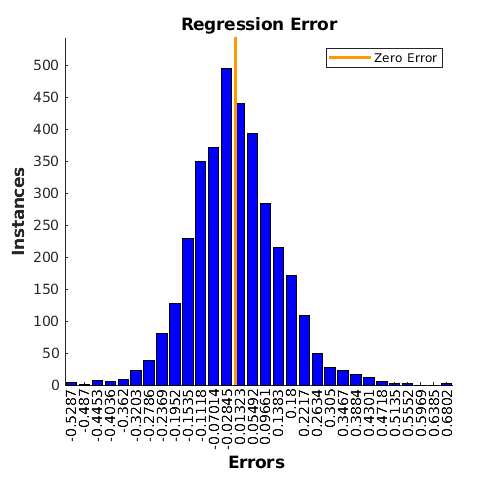

title('Regression Error')

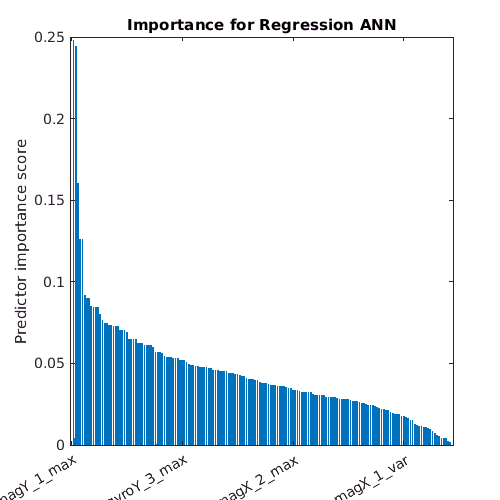


nexttile
Importance(datar,left_arm_data,'Regression ANN')


% nexttile
% ErrorInfo(classes,targetvals)
% title('Classification Error')
% 
% nexttile
% Importance(datac,left_arm_data, 'Classification ANN')
